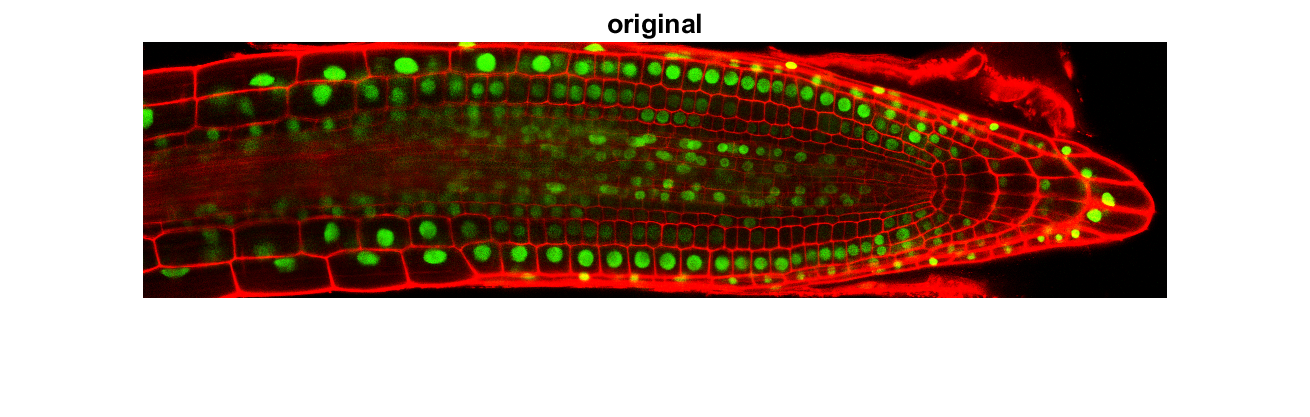

%% read image origin, StackNinja1.bmp image
img = imread("StackNinja1.bmp");

% Extract the individual red, green, and blue color channels.
redChannel = img(:, :, 1); % Red Channel
greenChannel = img(:, :, 2); % Green Channel
blueChannel = img(:, :, 3); % Blue Channel

% Greeness
GreenPic = (greenChannel -(redChannel+blueChannel)/2);
figure(1);
imshow(img);
title('original', 'FontSize', 10);

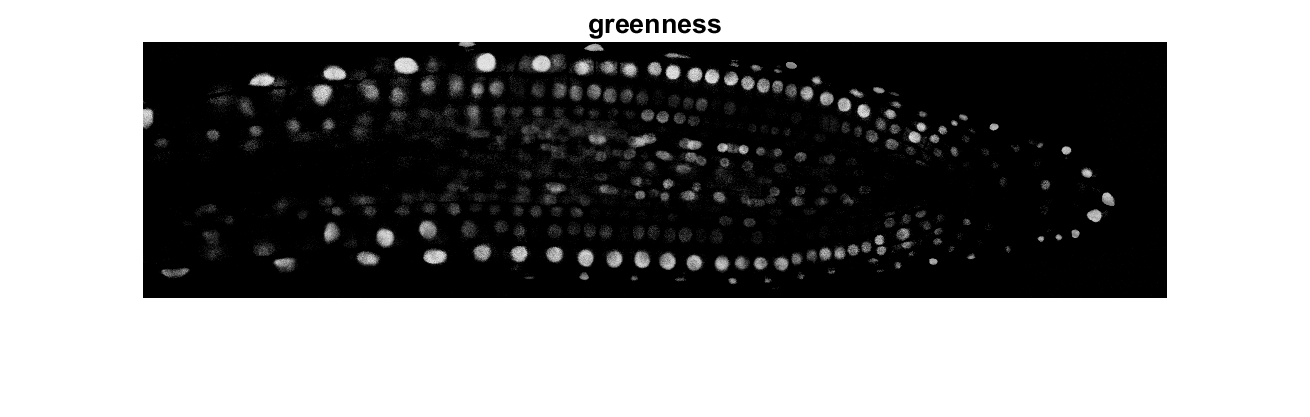

imshow(GreenPic);
title('greenness', 'FontSize', 10);



%% convert RGB to HSV 
hsvimg = rgb2hsv(img);

Error using rgb2hsv>parseInputs
R,G,B must all be the same size.

Error in rgb2hsv (line 36)
[r, g, b, isColorMap, isEmptyInput, isThreeChannel] = parseInputs(varargin{:});


% Extract out the H, S, and V images individually
hImage = hsvimg(:,:,1);
sImage = hsvimg(:,:,2);
vImage = hsvimg(:,:,3);

% Display the hue image.
h1 = imshow(hImage);
title('Hue Image', 'FontSize', 15);
% Set up an infor panel so you can mouse around and inspect the hue values.
hHuePI = impixelinfo(h1);
%%set(hHuePI, 'Units', 'Normalized', 'Position',[.34 .69 .15 .02]);
	